img = im2double(imread('car.bmp'));
mask = imread('mask.bmp') == 0;
len = 50;
[height, width] = size(img);

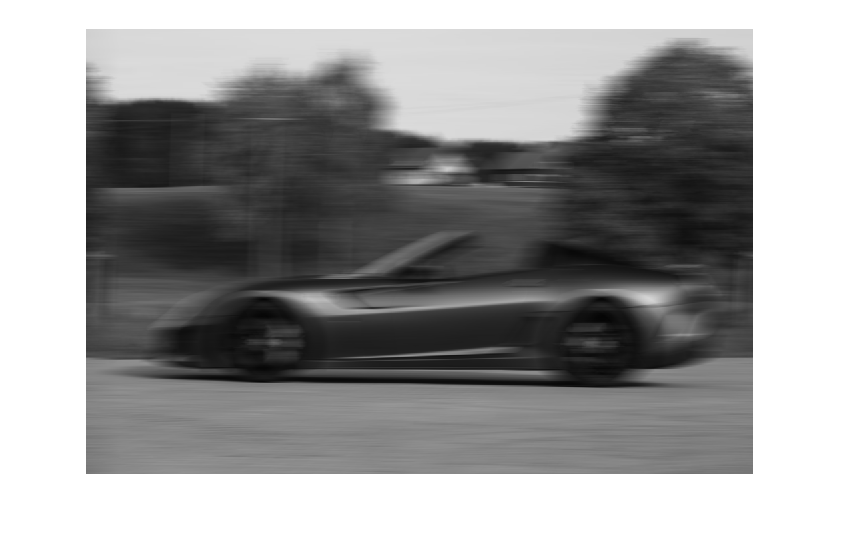

h = 2 * fspecial('motion',len * 2,0);
h(len+2:end) = 0;
motion = imfilter(img, h, 'circular');
imshow(motion);


levels = [0, 0.0001, 0.001, 0.01, 0.1, 1];

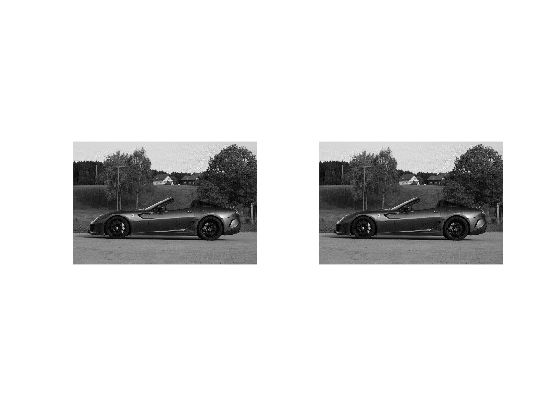

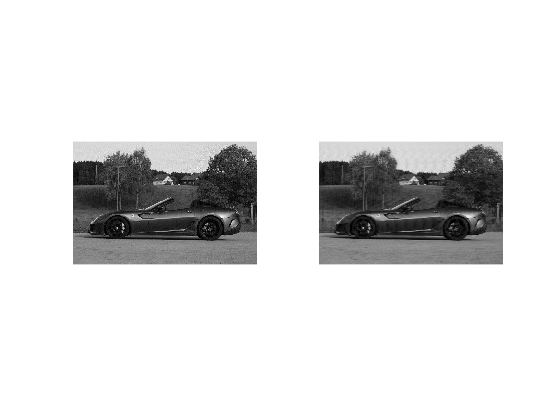

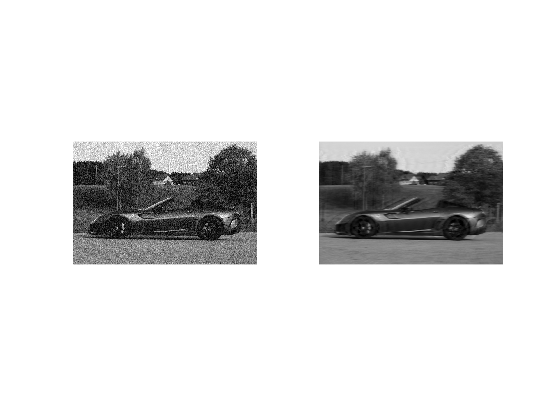

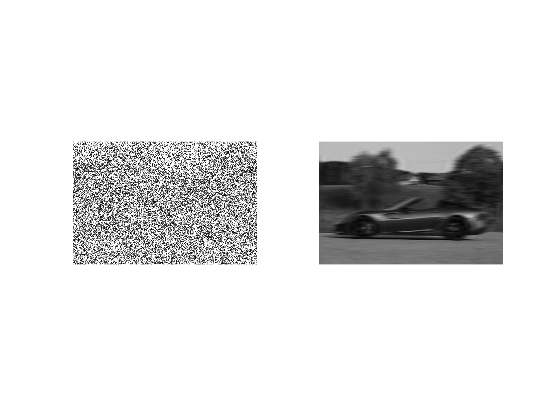

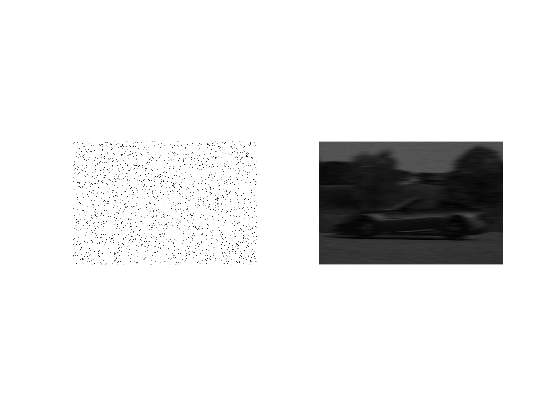

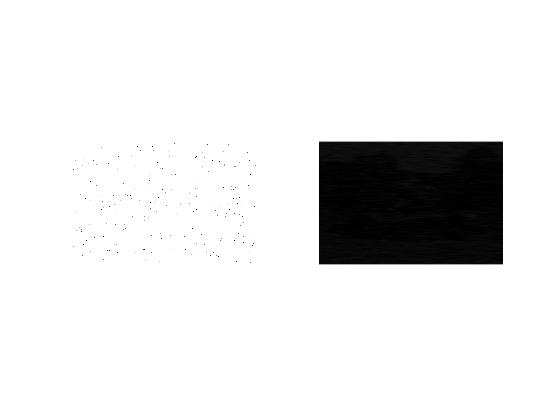

for noiselevel = levels
    name = num2str(noiselevel);    
    noise = noiselevel*randn(height, width);
    %g = imnoise(motion, 'gaussian', 0, snoiselevel);
    g = motion + noise;
    G = fft2(g, height, width);
    
    H = fft2(h, height, width);
    n = 0.00002;
    H(abs(H) < n) = n;
    R = ones(height, width)./H;
    F2 = G .* R;
    invH = abs(ifft2(F2));
    figure;title("var = " + name);
    subplot(1, 2, 1);imshow(invH);
    
    estimated_nsr = noiselevel / var(img(:));
    wnr1 = deconvwnr(g, h, estimated_nsr);
    wnr(:, 1:end-len) = wnr1(:, len+1:end);
    wnr(:, end-len+1:end) = wnr1(:, 1: len);
    subplot(1, 2, 2);imshow(wnr);
    imwrite(invH, "invH" + name + ".jpg", "jpg");
    imwrite(wnr, "wnr" + name + ".jpg", "jpg");
end